# Lab Session 3

## Question 1

format long e
A = posdef(5);
G = mychol(A);
Gcap = chol(A);
disp(norm(G - Gcap));

     2.242109385583635e-16



We can observe that $\textrm{norm}\left(G-\hat{G} \right)$ is within roundoff error.

## Question 2

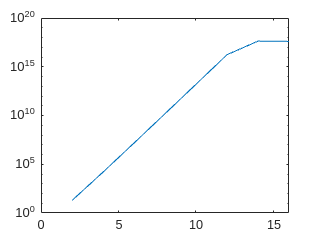

C = [];
N = 2:2:16;
for n = N
    H = hilb(n);
    C = [C; cond(H)];
end
semilogy(N, C);

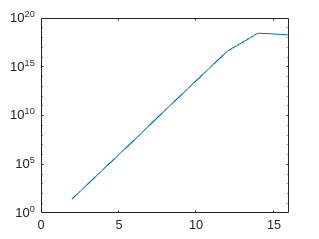

C = [];
N = 2:2:16;
for n = N
    H = hilb(n);
    C = [C; cond(H, 1)];
end
semilogy(N, C);


C = [];
N = 2:2:16;
for n = N
    H = hilb(n);
    C = [C; cond(H, inf)];
end
semilogy(N, C);

From the graphs we can say that cond(hilb(n)) = $O\left(\lambda^n \right)$ where n is the size of matrix and $\lambda$ is a constant.

## Question 3

n = 8;
H = hilb(n);
HI = invhilb(n);
x = rand(n, 1);
b = H*x;
x1 = H\b;
x2 = HI*b;
x3 = gepp_solve(H, b);
disp([cond(H) norm(x - x1)/norm(x) norm(x - x2)/norm(x) norm(x - x3)/norm(x)]);

     1.525757548992251e+10     6.212994689029529e-07     5.993203329633337e-07     6.213394119686222e-07



n = 10;
H = hilb(n);
HI = invhilb(n);
x = rand(n, 1);
b = H*x;
x1 = H\b;
x2 = HI*b;
x3 = gepp_solve(H, b);
disp([cond(H) norm(x - x1)/norm(x) norm(x - x2)/norm(x) norm(x - x3)/norm(x)]);

     1.602477880438442e+13     1.286482422755083e-05     1.023057857397132e-04     1.276529051278166e-05



n = 11;
H = hilb(n);
HI = invhilb(n);
x = rand(n, 1);
b = H*x;
x1 = H\b;
x2 = HI*b;
x3 = gepp_solve(H, b);
disp([cond(H) norm(x - x1)/norm(x) norm(x - x2)/norm(x) norm(x - x3)/norm(x)]);

     5.223178403453817e+14     5.712890327389575e-03     5.792325883307982e-03     5.712890327385495e-03



I think three digits are lost while computing $x_1$, $x_{2,\;}$and $x_3$. All are almost the same in terms of error.

## Question 4

n = 10;
H = hilb(n);
x = randn(n, 1);
b = H*x;
x1 = H \ b;
r = H*x1 - b;
disp([ norm(r)/norm(b) norm(x - x1)/norm(x)]);

     9.005569447958807e-17     1.658734080660178e-05



From this experiment we can conclude that small residue does not imply the accuracy of the computed answer as in this case $\frac{\textrm{norm}\left(x-x_1 \right)}{\textrm{norm}\left(x\right)}$ is the order of ${10}^{-4}$ which is considerable.

## Question 5

n = 32;
W = Wilkinson(n);
x = randn(n, 1);
b = W*x;
xcap = gepp_solve(W, b);
forward_error = norm(x - xcap, inf)/norm(x, inf);
condition_num = cond(A, inf);
rel_residual = norm(W*xcap - b, inf)/norm(b, inf);
x1cap = qr_solve(W, b);
forward_error1 = norm(x - x1cap, inf)/norm(x, inf);
rel_residual1 = norm(W*x1cap - b, inf)/norm(b, inf);
Methods = ["GEPP"; "QR"];
err = [forward_error; forward_error1];
res = [rel_residual; rel_residual1];
disp(condition_num);

     1.211045014345090e+02



table(Methods, err, res)

ans = 2×3 table
    Methods            err                     res         
    _______    ____________________    ____________________

    "GEPP"     8.61302409201111e-08    6.65064301233009e-08
    "QR"       6.50312039493942e-16    5.75647995906247e-16


(a) QR gives lower error of the computed solution

(b) It works well for QR decomposition

(c) QR gives lower value of $\frac{{||r||}_{\infty } }{{||b||}_{\infty } }$

(d) I think we can say that QR is more stable than GEPP.

## Functions

function P = posdef(n)
    r = rand(n, 1);
    D = diag(r);
    B = randn(n);
    [Q, R] = qr(B);
    P = Q'*D*Q;
end

function G = mychol(A)
    n = length(A);
    if(A(1, 1) < 0)
        disp('error');
    end
    if n == 1
        G = sqrt(A);
    else
        g11 = sqrt(A(1, 1));
        b = A(2:n, 1);
        g = b/g11;
        Gcap = mychol(A(2:n, 2:n) - g*g');
        G = [g11, g'; zeros(n - 1, 1), Gcap];
    end
end

function  [L,U,p] = gepp(A)
    sz = size(A);
    n=sz(2);
    p = (1:n);
    for k=1:n
        max_val=A(k,k);
        max_arg=k;
        for i=k+1:n
            if max_val<abs(A(i,k))
                max_val=abs(A(i,k));
                max_arg=i;
            end
        end
        if max_val==0
            continue;
        end
        A([k,max_arg],:)=A([max_arg,k],:);
        p([k,max_arg]) = p([max_arg,k]);
        for i=k+1:n
            A(i,k)=A(i,k)/A(k,k);
            for j=k+1:n
                A(i,j)=A(i,j)-A(i,k)*A(k,j);
            end
        end
    end
    L = tril(A,-1) + eye(n);
    U = triu(A);
end

function x = colbackward(U,b)
    n = size(b, 1);
    for j=n:-1:1
        if U(j, j) ~= 0
            b(j)=b(j)/U(j,j);
        else
            error('Singular Matrix encountered')
        end
        for i=j-1:-1:1
            b(i)=b(i)-U(i,j)*b(j);
        end
    end
    x = b;
end

function x = rowforward(L,b)
    n = size(b, 1);
    for k=1:n
        for j=1:k-1
            b(k)=b(k)-L(k,j)*b(j);
        end
        if L(k, k) ~= 0
            b(k)=b(k)/L(k,k);
        else
            error('Singular Matrix encountered')
        end
    end
    x = b;
end

function x = gepp_solve(A, b)
    [L, U, p] = gepp(A);

    Pb = b(p);
    y = rowforward(L, Pb);
    x = colbackward(U, y);
end

function W = Wilkinson(n)
    W = -1.*ones(n);
    W = tril(W);
    W = W + 2.*eye(n);
    W(:, end) = 1;
end

function x = qr_solve(A, b)
    [Q, R] = qr(A);
    x = colbackward(R, Q'*b);
end